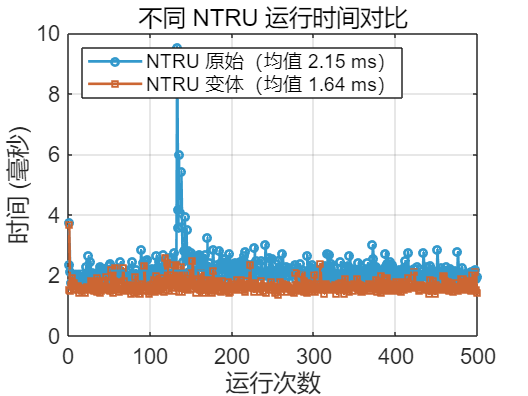

% 读取数据
time_plain = load('time_data.txt');  % 普通乘法
time_ntt = load('time_data_modified.txt');  % NTT乘法

% 确保数据长度一致
n = min(length(time_plain), length(time_ntt)); 
time_plain = time_plain(1:n);
time_ntt = time_ntt(1:n);
x = (1:n)';

% 计算平均值
mean_plain = mean(time_plain);var_plain = var(time_plain);
mean_ntt = mean(time_ntt);var_ntt = var(time_ntt);

% 开始绘图
figure;

% 原始数据线
h1 = plot(x, time_plain, '-o', 'LineWidth', 1.5, 'MarkerSize', 4, 'Color', [0.2 0.6 0.8]); hold on;
h2 = plot(x, time_ntt, '-s', 'LineWidth', 1.5, 'MarkerSize', 4, 'Color', [0.8 0.4 0.2]);
    
% 添加平均线（虚线）
plot(x, ones(n,1) * mean_plain, '--', 'Color', [0.2 0.6 0.8], 'LineWidth', 1.2);
plot(x, ones(n,1) * mean_ntt, '--', 'Color', [0.8 0.4 0.2], 'LineWidth', 1.2);

% 图形设置
xlabel('运行次数');
ylabel('时间 (毫秒)');
title('不同 NTRU 运行时间对比');
grid on;
set(gca, 'FontSize', 12);

% 设置图例，包含均值信息（保留 2 位小数）
legend(...
    sprintf('NTRU 原始（均值 %.2f ms）', mean_plain), ...
    sprintf('NTRU 变体（均值 %.2f ms）', mean_ntt), ...
    'Location', 'northwest' ...
);